Nbits = 1e4;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

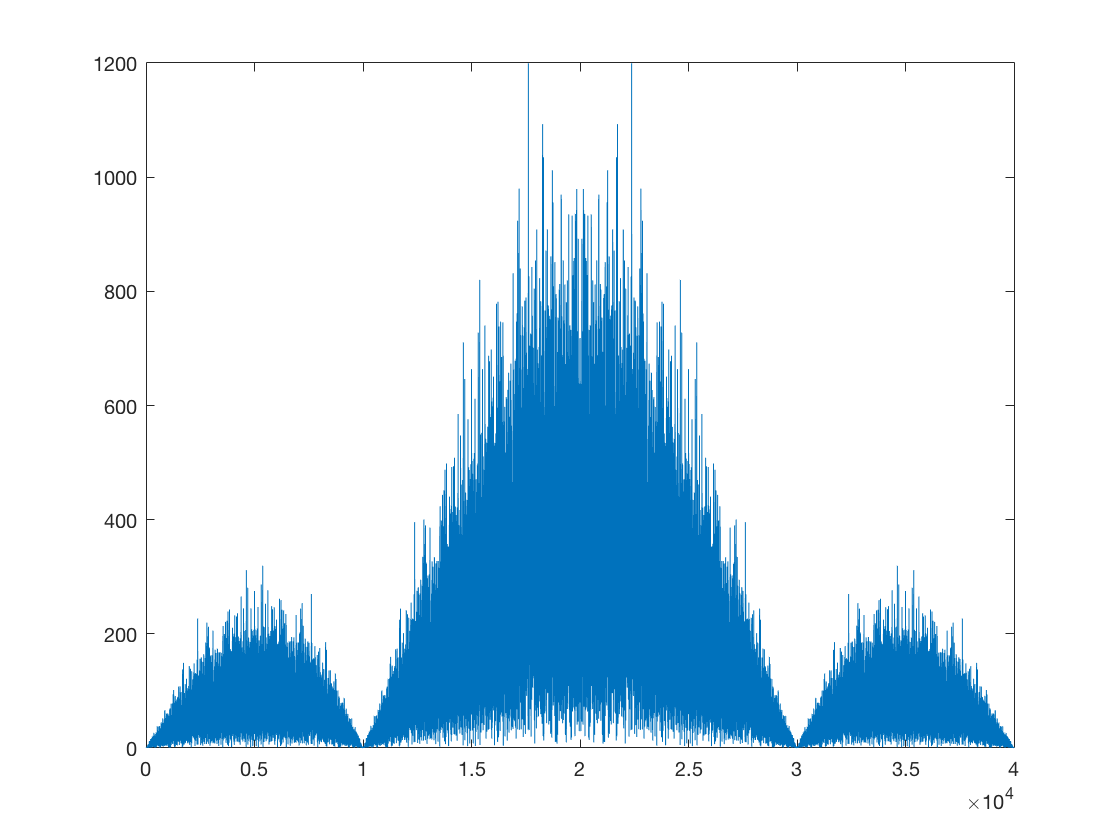

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);

% NRZ
for a=0:Nbits-1
    for b=1:SpS
        v_t(a*SpS+b) = in(a+1);
    end
end
figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t))))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);
for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10))
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim)
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    s_t = zeros(Nbits*SpS, 1);
    for a=1:4
        s_t(a) = 1;
    end
    S_f = (fft(s_t));
    H_rx = S_f;
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Scegliamo di campionare sul primo bit

    %samp_bit = 0;
    %r = zeros(Nbits, 1);
    %for a=1:Nbits
    %    r(a) = (y(a*4+samp_bit) > 0)*2-1;
    %end
    r = y(SpS:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err);
end

EbN0 = 1.5849

sigma = 1.1233

EbN0 = 1.9953

sigma = 1.0012

EbN0 = 2.5119

sigma = 0.8923

EbN0 = 3.1623

sigma = 0.7953

EbN0 = 3.9811

sigma = 0.7088

EbN0 = 5.0119

sigma = 0.6317

EbN0 = 6.3096

sigma = 0.5630

EbN0 = 7.9433

sigma = 0.5018

EbN0 = 10

sigma = 0.4472

EbN0 = 12.5893

sigma = 0.3986

EbN0 = 15.8489

sigma = 0.3552

Plotting

err_arr

err_arr =    367
   229
   135
    63
    25
     9
     5
     1
     0
     0


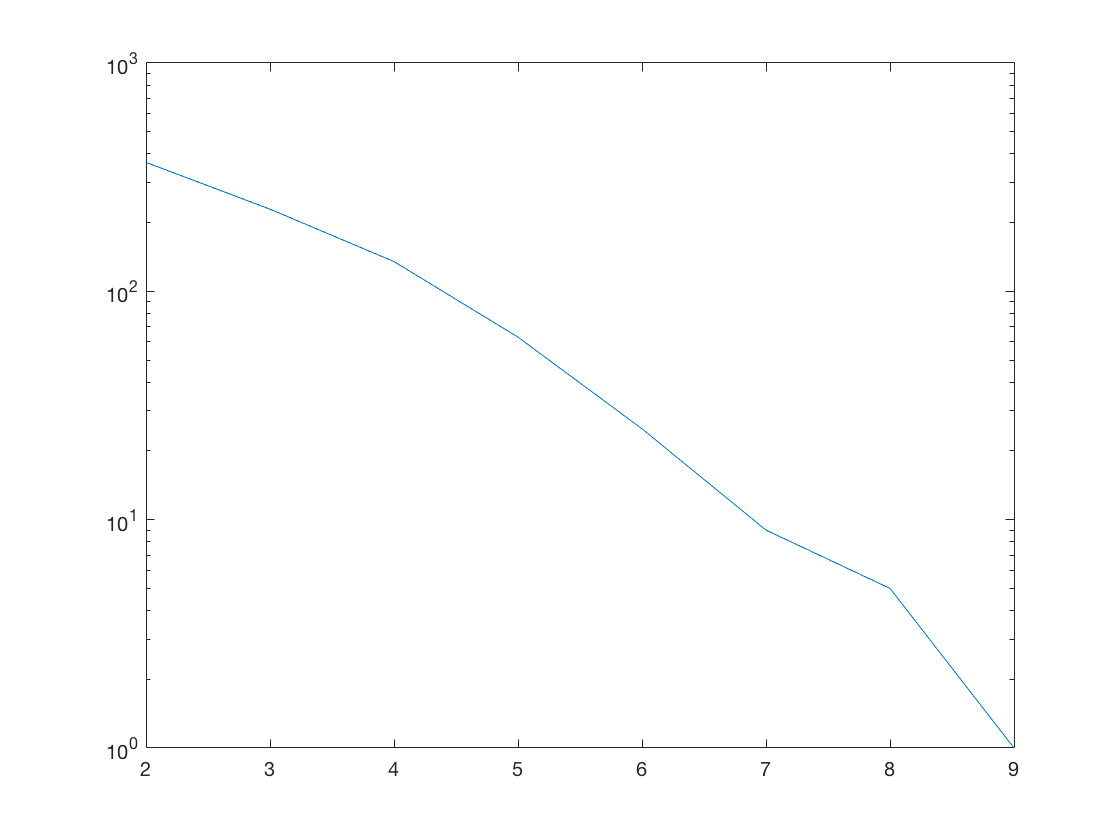

figure(2)
semilogy(2:12, err_arr)